clear; clc; close all;

% --- 1. Physical Dimensions ---
L_1 = 0.17;     % Crank arm length (meters)
L_3 = 0.15;     % Elevator horn length (meters)
x_c = 1.2;      % Horizontal distance to hinge
y_c = -0.8;     % Vertical distance to hinge
theta = linspace(-20, 20, 100) % Pilot input range (+/- 20 deg)

theta =   -20.0000  -19.5960  -19.1919  -18.7879  -18.3838  -17.9798  -17.5758  -17.1717  -16.7677  -16.3636  -15.9596  -15.5556  -15.1515  -14.7475  -14.3434  -13.9394  -13.5354  -13.1313  -12.7273  -12.3232  -11.9192  -11.5152  -11.1111  -10.7071  -10.3030   -9.8990   -9.4949   -9.0909   -8.6869   -8.2828   -7.8788   -7.4747   -7.0707   -6.6667   -6.2626   -5.8586   -5.4545   -5.0505   -4.6465   -4.2424   -3.8384   -3.4343   -3.0303   -2.6263   -2.2222   -1.8182   -1.4141   -1.0101   -0.6061   -0.2020


delta2 = [-11, -10, -9, -8, -7, -6, -5, -4, -3, -2, -1, 0, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10]

delta2 =    -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10


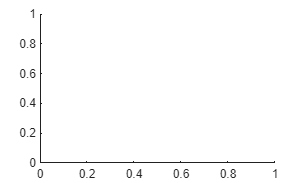

Ch = [-0.008970, -0.008082, -0.007180, -0.006220, -0.005241, -0.004236, -0.003211, -0.002203, -0.001186, -0.000168, 0.000861, 0.0018, 0.002898,  0.003910, 0.004918,  0.005911, 0.006903, 0.007859,  0.008759, 0.009622, 0.010441, 0.011173];
vel = linspace(0, 235, 90);
roe = 1.225;
c = 0.9;
b = 7.175;
hold on;

legend_labels = cell(1, length(vel));
% for i = 1:length(vel)
% 
% V = vel(i);
% q = 0.5*roe*V^2;
% H = Ch.*q.*c^2.*b;
% plot(delta2, H)
%  legend_labels{i} = sprintf('V = %.0f m/s', vel(i));
% end
% hold off;
% DisplayName = sprintf('V = %d m/s', vel(i));
% xlabel('Deflection angle \delta (deg)');
% ylabel('Hinge moment H (N·m)');
% xlim([-11, 10]);
% legend(legend_labels, Location='best');
% grid on;
% title('Hinge moment vs deflection angle for range of velocities');
% exportgraphics(gca, 'B737_Ho_vs_Delta.png', 'Resolution', 300);

% --- 2. Neutral Calibration (State: theta = 0, delta = 0) ---
start_angle = 220; % The "clocking" of the crank arm
th_n = 0;

% Coordinates of Crank Pin at Neutral
xa_n = L_1 * cosd(start_angle + th_n);
ya_n = L_1 * sind(start_angle + th_n);

% Coordinates of Hinge (Fixed)
xh = x_c; 
yh = y_c;

% Calculate the required Rod Length (L_2) to connect the points at Neutral
L_2 = sqrt((xh - xa_n)^2 + (yh + L_3 - ya_n)^2);

% Calculate geometric constants for rigging
S_n = sqrt((xh - xa_n)^2 + (yh - ya_n)^2);
Ga_n = atan2d(yh - ya_n, xh - xa_n);
Be_n = acosd((S_n^2 + L_3^2 - L_2^2) / (2 * S_n * L_3));
Phi = Ga_n + Be_n; % Rigging Constant

% --- 3. Simulation Loop ---
xa = L_1 * cosd(start_angle + theta);
ya = L_1 * sind(start_angle + theta);

S = sqrt((xh - xa).^2 + (yh - ya).^2);
Ga = atan2d(yh - ya, xh - xa);
Be = acosd((S.^2 + L_3^2 - L_2^2) ./ (2 .* S * L_3));

% Resulting Elevator Deflection
delta = (Ga + Be) - Phi

delta =   -24.4895  -23.9590  -23.4309  -22.9050  -22.3813  -21.8597  -21.3401  -20.8225  -20.3067  -19.7927  -19.2805  -18.7700  -18.2612  -17.7539  -17.2481  -16.7439  -16.2411  -15.7397  -15.2396  -14.7409  -14.2434  -13.7471  -13.2521  -12.7582  -12.2655  -11.7738  -11.2832  -10.7937  -10.3052   -9.8176   -9.3310   -8.8453   -8.3605   -7.8766   -7.3936   -6.9114   -6.4299   -5.9493   -5.4694   -4.9903   -4.5119   -4.0343   -3.5573   -3.0809   -2.6053   -2.1302   -1.6558   -1.1820   -0.7088   -0.2361



% --- 4. Visualization ---
figure('Color', 'w');
plot(theta, delta, 'b', 'LineWidth', 2); hold on;
 

grid on;
xlabel('Input Torque Tube Angle \theta (deg)');
ylabel('Elevator Deflection \delta (deg)');
title(' \delta(\theta)');

% Display results in Command Window
fprintf('--- Simulation Results ---\n');

--- Simulation Results ---


fprintf('Calculated Rod Length (L2): %.4f meters\n', L_2);

Calculated Rod Length (L2): 1.4359 meters


fprintf('Max Negative Deflection: %.2f deg\n', min(delta));

Max Negative Deflection: -24.49 deg


fprintf('Max Positive Deflection: %.2f deg\n', max(delta));

Max Positive Deflection: 22.92 deg


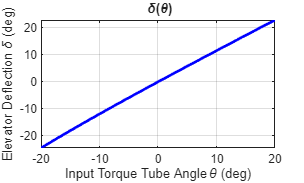


% --- 5. Export ---
exportgraphics(gca, 'B737_Elevator_Plot.png', 'Resolution', 300);

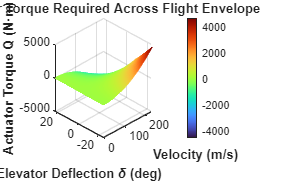

% --- Corrected Task 3: Actuator Torque Q vs theta ---

% Step 1 — Interpolate Ch onto the delta grid from simulation
Ch_interp = interp1(delta2, Ch, delta, 'linear', 'extrap'); % 1x100 vector

% Step 2 — Compute alfa from triangle geometry at each theta position
OA_x = xa; % Origin is 0, so xa - 0 = xa
OA_y = ya; 

elev_angle = Phi - delta; 
xb = xh + L_3 .* cosd(elev_angle);
yb = yh + L_3 .* sind(elev_angle);

AB_x = xb - xa;
AB_y = yb - ya;

% Step 3 — Perpendicular distances
cross_OA_AB = OA_x .* AB_y - OA_y .* AB_x;
e = abs(cross_OA_AB) ./ sqrt(AB_x.^2 + AB_y.^2); % 1x100 vector

esp = (asind((S./L_2).*sind(Be)) - delta - 90);
d = L_3 .* cosd(delta + esp); % 1x100 vector

% Step 4 — Dynamic pressure vector and Q Matrix Setup
q_vec = 0.5 * roe * vel.^2; % 1x90 vector of dynamic pressures

% Pre-allocate Q matrix: 100 rows (for delta) by 90 columns (for vel)
Q = zeros(length(delta), length(vel));

% Step 5 — Loop through velocities to populate Q
for j = 1:length(vel)
    % Calculate hinge moment for the j-th velocity (1x100 vector)
    H_curr = Ch_interp .* q_vec(j) .* c^2 .* b;
    
    % Calculate actuator torque for the j-th velocity (1x100 vector)
    Q_curr = -(H_curr .* e) ./ d;
    
    % Store the 1x100 result as a column in the Q matrix
    % The (:) forces Q_curr into a column vector shape
    Q(:, j) = Q_curr(:);
  

end
% --- Task 5: 3D Surface Plot of Q vs Velocity and Delta ---

figure('Color', 'w');

% Create the surface plot
% surf(X, Y, Z) -> X maps to columns (vel), Y maps to rows (delta)
surf(vel, delta, Q, 'EdgeColor', 'interp'); 

% Enhance the visuals
colormap turbo;     % 'turbo' or 'jet' provides good contrast for heatmaps
colorbar;           % Adds a legend for the Z-axis values
grid on;

% Label the axes
xlabel('Velocity (m/s)', 'FontWeight', 'bold');
ylabel('Elevator Deflection \delta (deg)', 'FontWeight', 'bold');
zlabel('Actuator Torque Q (N·m)', 'FontWeight', 'bold');
title('Actuator Torque Required Across Flight Envelope');

% Set a nice default 3D viewing angle (Azimuth, Elevation)
view(-45, 30); 

%Optional: Export the 3D plot
 exportgraphics(gca, 'B737_Q_SurfacePlot.png', 'Resolution', 300);


% %task 3
% %% --- Task 3: Actuator Torque Q vs theta ---
% 
% % Step 1 — Interpolate Ch onto the delta grid from simulation
% % delta is (1x100), delta2 is (1x22) — interpolate Ch onto delta
% Ch_interp = interp1(delta2, Ch, delta, 'linear', 'extrap');
% 
% % Step 2 — Choose a velocity for Q calculation (worst case = max vel)
% V_Q   = 235;           % m/s
% q_Q   = 0.5 * roe * vel.^2;
% H_interp = Ch_interp .* q_Q .* c^2 .* b;  % now (1x100)
% 
% % Step 3 — Compute alfa from triangle geometry at each theta position
% % Vector OA at each theta
% OA_x = xa - 0;        % O is at origin (0,0)
% OA_y = ya - 0;
% 
% % Point B on elevator arm at each theta
% % B = C + L3 * unit vector along elevator arm direction
% % Elevator arm direction angle = Phi - delta (changes with delta)
% elev_angle = Phi - delta;   % angle of elevator arm from reference
% xb = xh + L_3 .* cosd(elev_angle);
% yb = yh + L_3 .* sind(elev_angle);
% 
% % Vector AB at each theta
% AB_x = xb - xa;
% AB_y = yb - ya;
% 
% % Step 4 — Perpendicular distances using cross product
% % e = perp distance from O to rod line = |OA x AB| / |AB|
% cross_OA_AB = OA_x .* AB_y - OA_y .* AB_x;
% e = abs(cross_OA_AB) ./ sqrt(AB_x.^2 + AB_y.^2);
% 
% % d = perp distance from C to rod line = L3 * sin(beta) = already have Be
% esp = (asind((S/L_2).*sind(Be)) - delta - 90)
% d = L_3 .* cosd(delta + esp);
% 
% % Step 5 — Actuator torque
% Q = -(H_interp .* e) ./ d;   % (N.m)
% figure('Color','w'); hold on;
% legend_labels_Q = cell(1, length(vel));
% 
% Q = zeros(size(delta,2), size(vel,2));
% for i = 1:size(Q, 1)
%     for j = 1:size(Q, 2)
%         Q(i,j) = -(H_interp(j) .* e) ./ d
%     end 
% end


%for i = 1:length(vel)
  %  V_Q      = vel(i);
  %  q_Q      = 0.5 * roe * V_Q^2;
 %   H_interp = Ch_interp .* q_Q .* c^2 .* b;
  %  Q        = -(H_interp .* e) ./ d;
   % plot(theta, Q, LineWidth=1.5);
    %legend_labels_Q{i} = sprintf('V = %.0f m/s', vel(i));
%end
%
%hold off;
%xlabel('Input angle \theta (deg)');
%ylabel('Actuator torque Q (N·m)');
%legend(legend_labels_Q, Location='best');
%grid on;
%title('Actuator torque vs input angle for range of velocities');
%exportgraphics(gca, 'B737_Q_vs_theta_velocities.png', Resolution=300);
% Step 6 — Plot
%figure('Color','w');
% plot(theta, Q, 'r', LineWidth=1.5);
% grid on;
% xlabel('Input angle \theta (deg)');
% ylabel('Actuator torque Q (N·m)');
% title(sprintf('Actuator torque vs input angle  —  V = %.0f m/s', V_Q));
% exportgraphics(gca, 'B737_Q_vs_theta.png', Resolution=300);
% 
% 
% %% --- Task 4: High-Resolution Actuator Torque vs. Deflection ---
% 
% figure('Color', 'w');
% hold on;
% 
% % Pre-allocate legend cell array
% legend_labels_Q_delta = cell(1, length(vel));
% 
% for i = 1:length(vel)
%     V_curr = vel(i);
%     q_curr = 0.5 * roe * V_curr^2;
% 
%     % 1. Use the interpolated Ch (Ch_interp) calculated for the full 'delta' range
%     % H_interp is the hinge moment across all 100 simulation points
%     H_interp_curr = Ch_interp .* q_curr .* c^2 .* b;
% 
%     % 2. Calculate Q using the kinematic leverage (e/d) for all points
%     % Note: Q = (Moment * Load_Arm) / Actuator_Arm
%     Q_full = -(H_interp_curr .* e) ./ d;
% 
%     % 3. Plot against the full 'delta' array (from kinematics)
%     plot(delta, Q_full, 'LineWidth', 1.5);
% 
%     legend_labels_Q_delta{i} = sprintf('V = %.0f m/s', V_curr);
% end
% 
% hold off;
% grid on;
% xlabel('Elevator Deflection \delta (deg)');
% ylabel('Required Actuator Torque Q (N·m)');
% title('Actuator Torque vs Elev Deflection');
% legend(legend_labels_Q_delta, 'Location', 'best');
% 
% % Set x-limits to the actual range achieved by the kinematics
% xlim([min(delta) max(delta)]);
% yticks(-5000:1000:5000);
% % Export for report
% exportgraphics(gca, 'B737_Q_vs_Delta_FullRange.png', 'Resolution', 300);

